resultthree = "resultthree/";
resultmitsuba = "resultmitsuba/";
ana_result = "analysisresult/";

% 事前に定義された行列と対応する行名と列名
rowNames = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
rowNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
colNames = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];

%-----------------------------------
% three parts
%-----------------------------------
threedataMatrix = zeros(4, 15);

% Excelファイル名
dirInfo = dir(resultthree);
filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

for foldernum =1:numFiles
    filename = fullfile(resultthree, filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(rowNames)
        sheetName = rowNames{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames == idNum);
            rowIndex = find(strcmp(rowNames, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                threedataMatrix(rowIndex, colIndex) = threedataMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end

resultthree/kawahara_three.xlsx
resultthree/killian_three.xlsx
resultthree/kyou_three.xlsx
resultthree/miyoshi_three.xlsx



disp(threedataMatrix);

  1 列から 13 列

   -1.1995    0.8701    0.8985    0.9152    1.7571    0.6415    1.9004    2.0437    0.1548   -1.8562   -2.3927    2.9140   -0.6594
   -1.8033    0.0857    1.4136    1.2172    1.6608    1.4310    2.0785    1.8189   -1.8157   -1.6884   -1.2597    2.9605    0.3847
   -1.2449    0.6068    0.7785    3.5544    1.3053    1.4654   -0.9387   -0.2803   -2.4134   -3.0908    2.3240    1.8255    0.9218
   -1.9459    0.2587   -0.9440    2.6344    1.3335    1.1334   -0.7556    0.4909   -3.0414   -0.9113    1.4484    1.5425    2.1708

  14 列から 15 列

   -4.0018   -1.9856
   -4.5909   -1.8929
   -4.5616   -0.2519
   -1.6453   -1.7692




%-----------------------------------
% mitusba parts
%-----------------------------------
mitsubadataMatrix = zeros(4, 15);

% Excelファイル名
dirInfo = dir(resultmitsuba);
filesNames = {dirInfo(~ismember({dirInfo(:).name}, {'.', '..'})).name};
numFiles = sum(~ismember({dirInfo(:).name}, {'.', '..'}));

for foldernum =1:numFiles
    filename = fullfile(resultmitsuba, filesNames{foldernum});
    disp(filename);
    for materialnum = 1:length(rowNames)
        sheetName = rowNames{materialnum};
        sheetData = readtable(filename, 'Sheet', sheetName, 'ReadVariableNames', false);
        
        names = sheetData{:, 1};
        scores = sheetData{:, 2};
        
        for i = 1:length(names)
            nameStr = names{i};
            idStr = regexp(nameStr, '\d+', 'match');
            idNum = str2double(idStr(end));
            colIndex = find(colNames == idNum);
            rowIndex = find(strcmp(rowNames, sheetName));
            if ~isempty(colIndex) && ~isempty(rowIndex)
                mitsubadataMatrix(rowIndex, colIndex) = mitsubadataMatrix(rowIndex, colIndex) + scores(i);
            end
        end
    end
end

resultmitsuba/kawahara_mitsuba.xlsx
resultmitsuba/killian_mitsuba.xlsx
resultmitsuba/kyou_mitsuba.xlsx
resultmitsuba/miyoshi_mitsuba.xlsx



disp(mitsubadataMatrix);

  1 列から 13 列

   -0.9259    1.5226   -0.0513    1.2941    1.3509    1.4145    0.9790    1.4063   -0.7098   -1.5968   -2.4123    1.7511    1.1884
   -1.1320   -0.5454   -0.0288    1.6316   -0.0128    1.8601    1.5167    1.7438   -2.2544   -2.1733    0.4863    1.7749    2.2915
   -1.7273    0.0343   -0.5092    2.9987    0.8645    1.4081    0.0628    2.3831   -2.5959   -1.3678    1.4198    2.0936    1.7800
   -2.4554   -2.2390   -0.1475    2.6890   -0.5427    0.2849   -0.1475    3.3314   -3.3706   -2.3825    0.7556    1.3152    2.8162

  14 列から 15 列

   -3.1775   -2.0333
   -4.5856   -0.5724
   -4.7020   -2.1426
    0.0687    0.0242



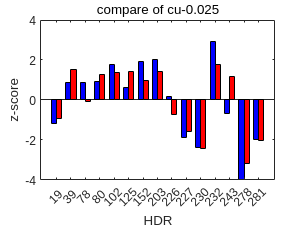

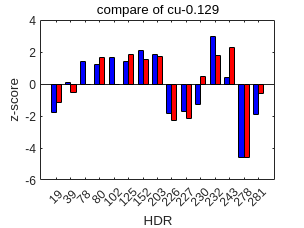

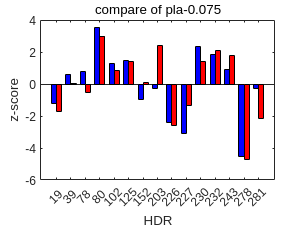

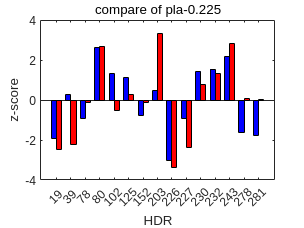

%-----------------------------------
% analysis
%-----------------------------------
%bar graph
for row = 1:4
    figure;
    bar_width = 0.35;
    x = 1:length(colNames);

    % threedataのプロット
    bar(x - bar_width/2, threedataMatrix(row, :), bar_width, 'FaceColor', 'b', 'DisplayName', 'three'); 
    hold on;
    
    % mitsubadataのプロット
    bar(x + bar_width/2, mitsubadataMatrix(row, :), bar_width, 'FaceColor', 'r', 'DisplayName', 'mitsuba'); 
    
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames);
    xlabel('HDR'); 
    ylabel('z-score');
    title(['compare of ' rowNames2{row}]);
    %legend('show');
end


%correlation_coefficients
correlation_coefficients = zeros(1, 4);
for row = 1:4
    data_three = threedataMatrix(row, :);
    data_mitsuba = mitsubadataMatrix(row, :);
    corr_matrix = corrcoef(data_three, data_mitsuba);
    correlation_coefficients(row) = corr_matrix(1, 2);
end

disp(correlation_coefficients);

    0.9041    0.8548    0.8550    0.7114

